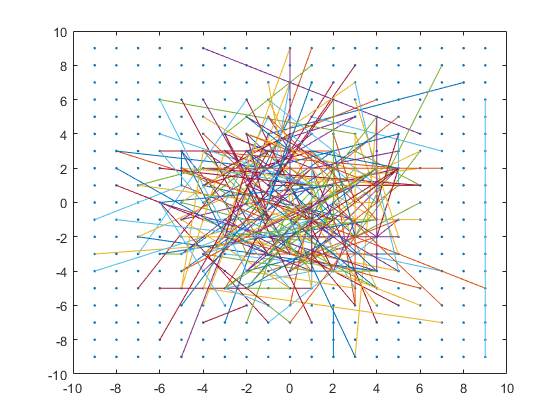

clc;clear;
figure;hold on;
imgpath = 'M:\Documents\stitching\stitching\hill\hill';  
buildingScene = imageDatastore(imgpath);
montage(buildingScene.Files);

numImages = numel(buildingScene.Files);


patten = brief_pattern_generator();

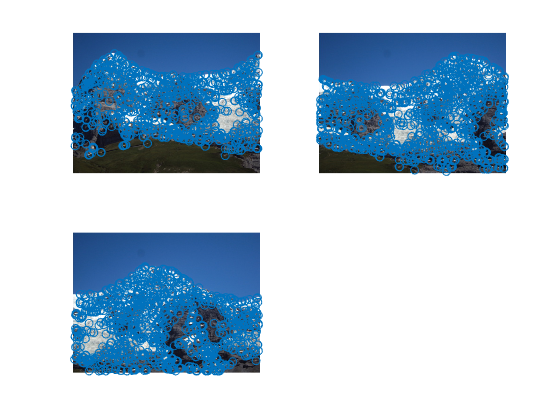

% feature detect
seq.features = cell(numImages,1);
seq.descriptors = cell(numImages,1);
seq.imgs = cell(numImages,1);
for n=1:numImages
im1 = readimage(buildingScene, n);
  if size(im1,3) == 3
        im1gray = rgb2gray(im1);
    else
        im1gray = im1;
    end
 img1 = single(im1gray);
corner = fast(img1);
descriptor = extractdes(img1,corner,patten);
    seq.corner{n} = corner;
    seq.descriptors{n} = descriptor;
    seq.imgs{n} = im1;
    imageSize(n,:) = size(im1gray);
end
%check answer
subplot(2,2,1);
imshow(seq.imgs{1,1});
hold on

plot(seq.corner{1,1}(:,2),seq.corner{1,1}(:,1),'o');
subplot(2,2,2);
imshow(seq.imgs{2,1});
hold on
plot(seq.corner{1,2}(:,2),seq.corner{1,2}(:,1),'o');
subplot(2,2,3);
imshow(seq.imgs{3,1});
hold on
plot(seq.corner{1,3}(:,2),seq.corner{1,3}(:,1),'o');

seq.matchingpair=cell(numImages,1);
pairs = nchoosek(1:numImages,2);
for i = 1:size(pairs,1)
    descriptor1 = seq.descriptors{pairs(i,1)};
    descriptor2 = seq.descriptors{pairs(i,2)};
    matchingpair = bruteforce(descriptor1, descriptor2);
    seq.matchingpair{i}=matchingpair;
end